# 適切な図の設定

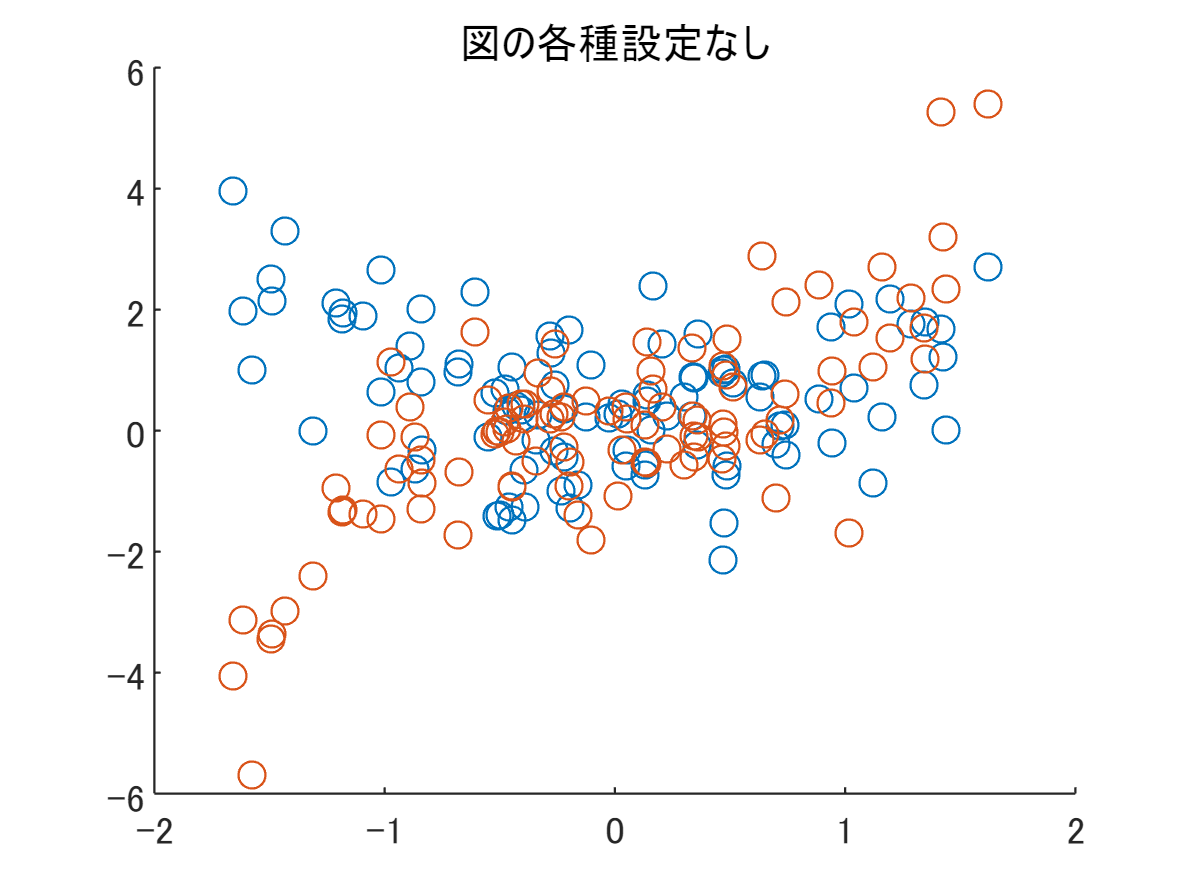

clear;clc;close all;
rng(1); % コメントを外すと書籍と同じ図が得られる
x=randn(100,1)*0.8;
y=x.^2+randn(100,1);
y2=x.^3+randn(100,1);
figure
scatter(x,y);hold on;scatter(x,y2);
title('図の各種設定なし');
exportgraphics(gcf,'fig_figureSettingSample01.pdf');

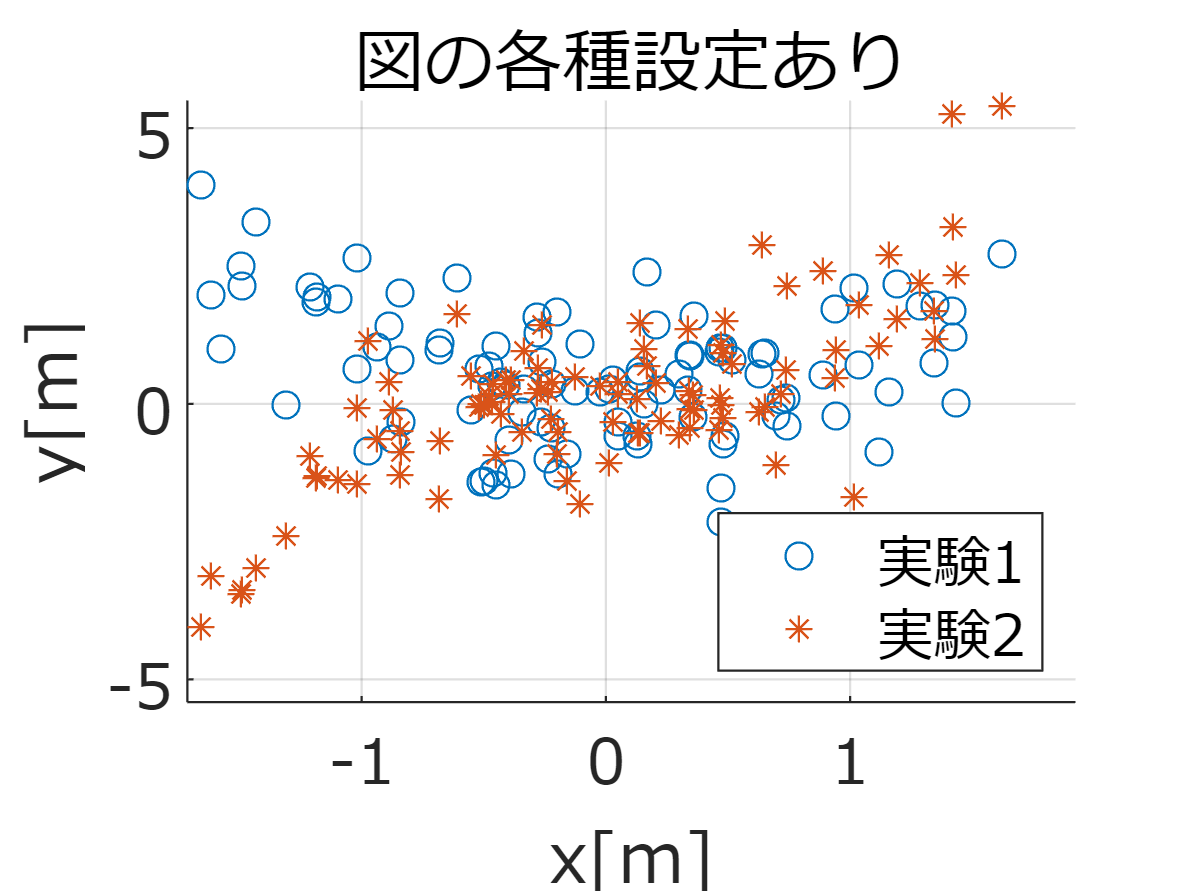


figure
scatter(x,y);hold on;scatter(x,y2,'*'); %異なるデータのマーカ種は変えた方が良い．
grid on;    %格子線を適切に追加する．
set(gca,'fontname','メイリオ','fontsize',14);   %フォントは読みやすいものを選ぶ
xlabel('x[m]');ylabel('y[m]');  % 縦横軸それぞれに意味と単位を明記する
legend({'実験1','実験2'},'Location','southeast'); %凡例を追加する．データと重複しない配置を選択する．
title('図の各種設定あり');
exportgraphics(gcf,'fig_figureSettingSample02.pdf');